# Assignment 3

This live script is for Mechatronic System Design: Assignment 3.

clear; clc; close all;

### Section A: Computing Real Feedback Error

Load controller from Assignment 2

shapeit_final = load("Assignment 2/A.1_C_final.mat", "shapeit_data"); % Load Final Controller from ShapeIt
load ("Assignment 2/MSD2024_P2_Plant.mat") ; % Load plant

% Controller
C = tf(shapeit_final.shapeit_data.C_tf.Numerator, shapeit_final.shapeit_data.C_tf.Denominator)


C =
 
  0.01098 s^4 + 16.38 s^3 + 2.412e05 s^2 + 3.075e08 s + 8.062e10
  --------------------------------------------------------------
       0.001989 s^4 + 56.2 s^3 + 7.029e04 s^2 + 2.139e07 s
 
Continuous-time transfer function.
Model Properties


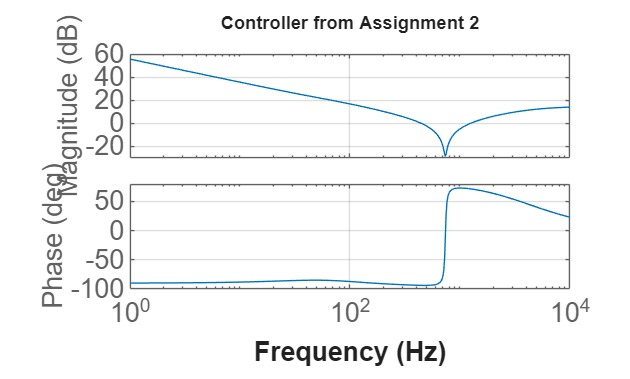


% Define bode options
opts = bodeoptions('cstprefs');
opts.FreqUnits = 'Hz';
opts.XLim= [1 10000];
opts.PhaseVisible = 'on';
opts.PhaseWrapping = 'off';
opts.Grid = 'on';
opts.XLabel.String = 'Frequency';
opts.XLabel.FontSize = 16;
opts.XLabel.FontWeight = 'bold';
opts.YLabel.String = {'Magnitude','Phase'};
opts.YLabel.FontSize = 16;
opts.YLabel.FontWeight = 'bold';
opts.TickLabel.FontSize = 16;

figure(1);clf(1);
bode(C, opts);
title('Controller from Assignment 2')

### Analyze system at 10 Hz

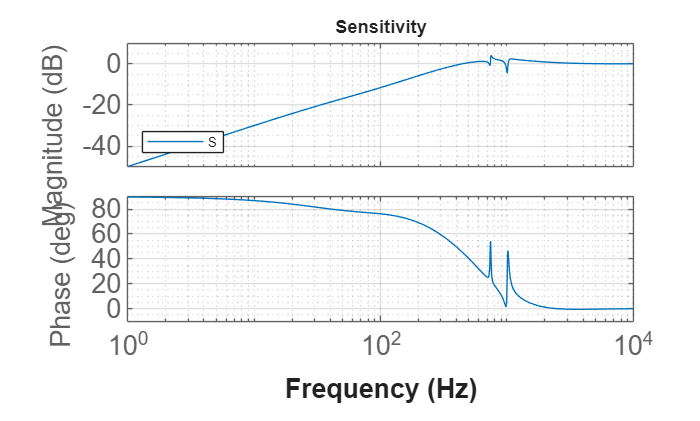

r = 10e-6; % reference signal at 10 Hz (m)
d = 20;    % process disturbance at 10 Hz (V)
n = 10e-9; % output disturbance at 10 Hz (m)

% Open Loop
L = G*C;

% Define sensitivity functions
S = 1 / (1 + L); % Sensitivity function
PS = G / (1 + L); % Process sensitivity
T = L / (1 + L); % Complementary sensitivity

figure(2); clf(2);
bode(S, opts);title('Sensitivity')
legend(Location='southwest')
grid on; grid minor; 

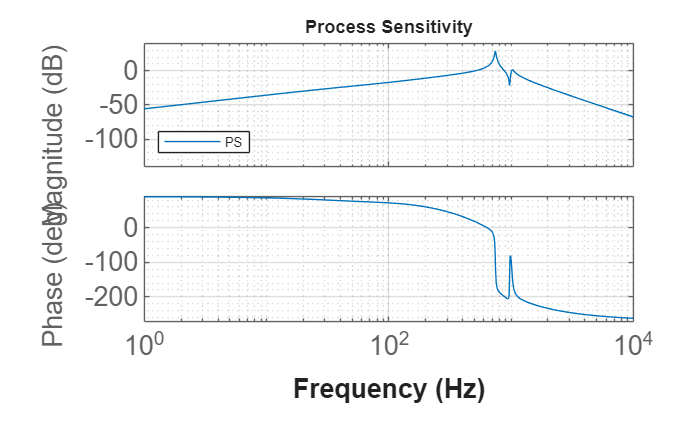


figure(3); clf(3);
bode(PS, opts);title('Process Sensitivity')
legend(Location='southwest')
grid on; grid minor; 

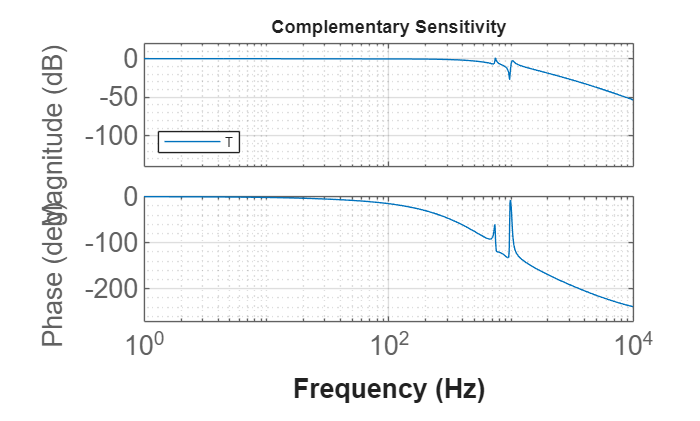


figure(4);clf(4);
bode(T,opts); title('Complementary Sensitivity')
legend(Location='southwest')
grid on; grid minor;


% Frequency of interest
f = 10; % Frequency in Hz
omega = 2 * pi * f; % Angular frequency

% Calculate the magnitudes at 10 Hz
S_mag = abs(freqresp(S, omega));
PS_mag = abs(freqresp(PS, omega));
T_mag = abs(freqresp(T, omega));

% Compute the real error
e_real = sqrt((S_mag * r)^2 + (PS_mag * d)^2 + (T_mag * n)^2);

% Display the result
fprintf('Real error at 10 Hz: %.2e\n', e_real);

Real error at 10 Hz: 3.31e-01


### Case 2: How to improve performance at 10 Hz?

% Add an anti - notch filter at 10 Hz

shapeit_notch = load("C_final_with_notch_10_hz.mat", "shapeit_data");

C2 = tf(shapeit_notch.shapeit_data.C_tf.Numerator, shapeit_notch.shapeit_data.C_tf.Denominator)


C2 =
 
  0.01098 s^6 + 16.72 s^5 + 2.417e05 s^4 + 3.151e08 s^3 + 9.123e10 s^2 + 3.747e12 s + 3.183e14
  --------------------------------------------------------------------------------------------
       0.001989 s^6 + 56.21 s^5 + 7.065e04 s^4 + 2.205e07 s^3 + 4.119e08 s^2 + 8.443e10 s
 
Continuous-time transfer function.
Model Pr

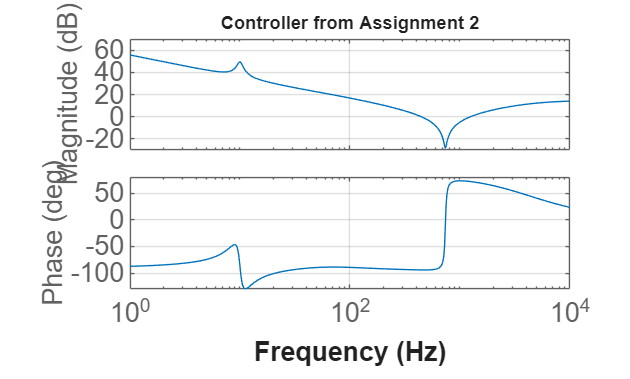


figure(1);clf(1);
bode(C2, opts);
title('Controller from Assignment 2')

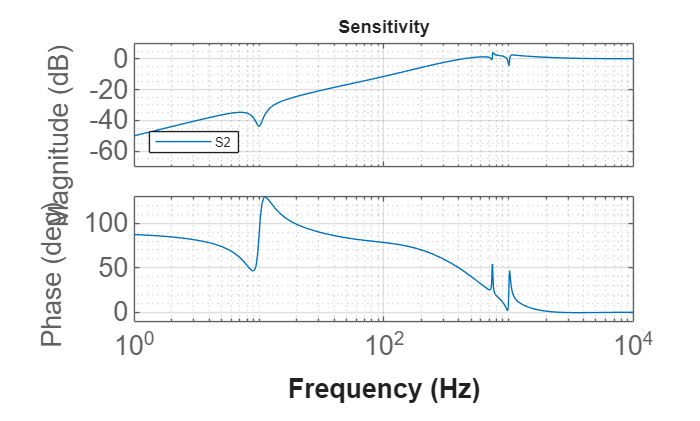


% Open Loop
L2 = G*C2;

% Define sensitivity functions
S2 = 1 / (1 + L2); % Sensitivity function
PS2 = G / (1 + L2); % Process sensitivity
T2 = L / (1 + L2); % Complementary sensitivity

figure(2); clf(2);
bode(S2, opts);title('Sensitivity')
legend(Location='southwest')
grid on; grid minor; 

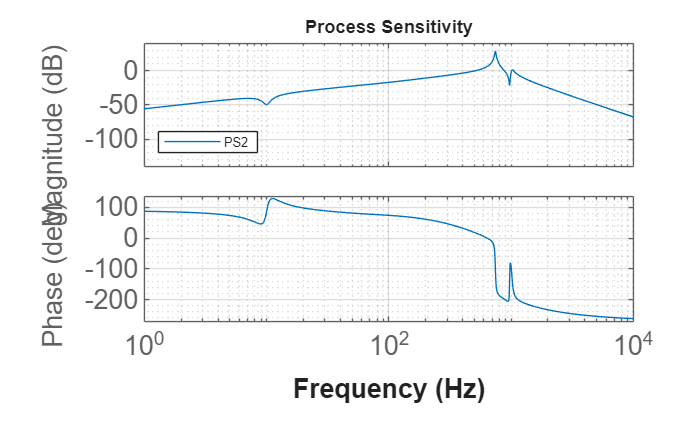


figure(3); clf(3);
bode(PS2, opts);title('Process Sensitivity')
legend(Location='southwest')
grid on; grid minor; 

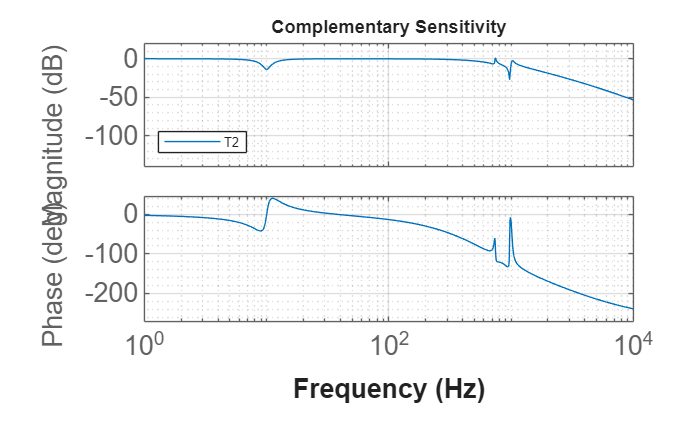


figure(4);clf(4);
bode(T2,opts); title('Complementary Sensitivity')
legend(Location='southwest')
grid on; grid minor;


% Calculate the magnitudes at 10 Hz
S_mag_2 = abs(freqresp(S2, omega));
PS_mag_2 = abs(freqresp(PS2, omega));
T_mag_2 = abs(freqresp(T2, omega));

% Compute the real error
e_real_2 = sqrt((S_mag_2 * r)^2 + (PS_mag_2 * d)^2 + (T_mag_2 * n)^2);

% Display the result
fprintf('Real error at 10 Hz: %.2e\n', e_real_2);

Real error at 10 Hz: 6.63e-02
